% Code reads in an excel file to plot rainfall vs drip logger count
% Date is in column 1, rainfall is in column 2 and 20 loggers data is in columns 3 to 22
% First graph is logger drip data for loggers 1 to 7 
% Second graph is logger drip data for loggers 8 to 13 
% Third graph is logger drip data for loggers 14 to 15 
% Fourth graph is logger drip data for loggers 16 to 20

% Define the file name and sheet 
filename = 'Rainfall_MM_Loggers_daily_SUM.csv'; % Replace with your actual file name

% Read the data from the Excel file
data = readtable(filename);

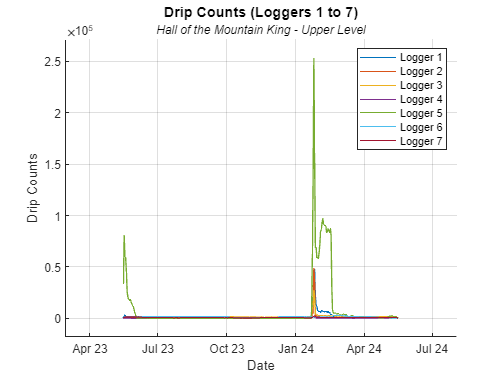

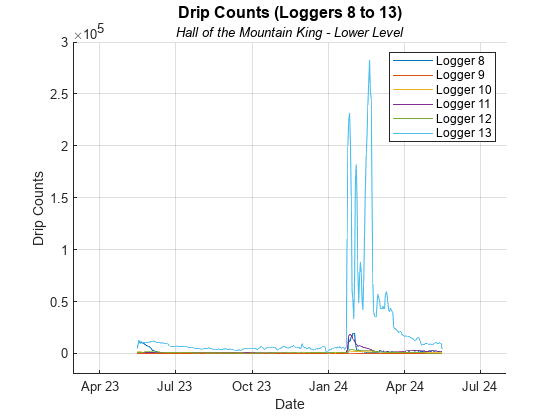

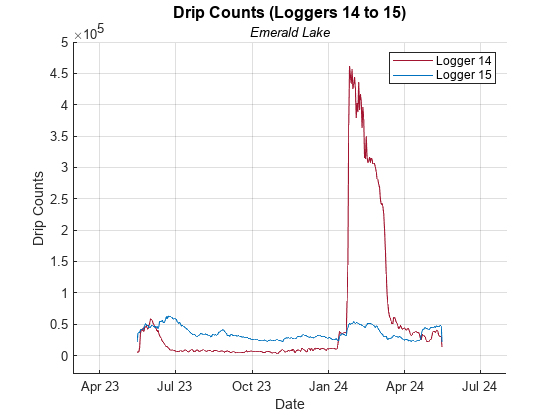

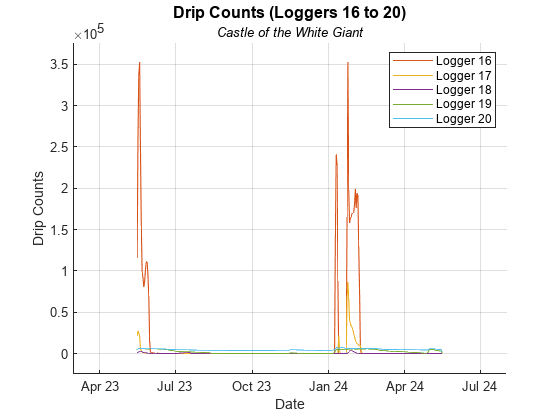


% Extract columns for date and loggers
date = data{:, 1};  % Column 1: Date
loggers = data{:, 3:22}; % Columns 3 to 22: Logger data

% Define the logger groups
loggerGroups = {
    1:7;   % Loggers 1 to 7
    8:13;  % Loggers 8 to 13
    14:15; % Loggers 14 to 15
    16:20  % Loggers 16 to 20
};

% Define a colormap with enough unique colors
numLoggers = size(loggers, 2);
colors = lines(numLoggers); % Generates a set of colors based on the number of loggers

% Define unique subtitles for each plot
unique_subtitles = {
    'Hall of the Mountain King - Upper Level',
    'Hall of the Mountain King - Lower Level',
    'Emerald Lake',
    'Castle of the White Giant'
};

% Loop through each group of loggers
for j = 1:length(loggerGroups)
    
    % Create a new figure for each logger group
    figure;

    % Hold on to plot all loggers in the same figure
    hold on; 
    
    % Plot each logger with a unique color
    for i = loggerGroups{j}
        plot(date, loggers(:, i), 'Color', colors(i, :), 'DisplayName', ['Logger ' num2str(i)]);
    end

    % Set labels and title
    xlabel('Date');
    ylabel('Drip Counts');

    % Create main title showing the logger range
    mainTitle = ['Drip Counts (Loggers ' num2str(loggerGroups{j}(1)) ' to ' num2str(loggerGroups{j}(end)) ')'];
    title(mainTitle, 'FontSize', 12);
    
    % Get the unique subtitle for the current plot
    subtitleText = unique_subtitles{j};

    % Set the subtitle
    subtitle(subtitleText, 'FontSize', 10, 'FontAngle','italic' );
    
    % Adjust plot
    axis padded;
    grid on;
    legend show;
    hold off;

    % Optionally, you can save the figure
    % saveas(gcf, ['Drip_Counts_Logger_Columns_' num2str(logger_ranges{i}(1)) '_' num2str(logger_ranges{i}(end)) '.png']);
end